Ts = 0.01;
% m = 0.217;
% l = 0.240;
m = 0.1401;
l = 0.0307;
g = 9.81;
I_cfRod = 0.0000060512;

I_tot_init = 0.003;
c_init = 0.0001;

% load("knownMassTest.mat");     % Load in timestamp & orientation data for only the free swinging motion
% [y,tVec] = resample(data(:,2)*(pi()/180), data(:,1)-data(1:1), 1/Ts);  % Resample data to ensure consistent fixed timesteps

data = iddata(y,[],Ts,"Name","SwingTest");
data.OutputName = "theta";
data.OutputUnit = "rad";
data.Tstart = 0;
data.TimeUnit = 's';

sys_linear = idgrey('linear_greybox_ss', {m, g, l, I_tot_init, c_init}, 'c');
sys_linear.Structure.Parameters(1).Free = false;
sys_linear.Structure.Parameters(2).Free = false;
sys_linear.Structure.Parameters(3).Free = false;
sys_linear.Structure.Parameters(4).Minimum = 0;
sys_linear.Structure.Parameters(5).Minimum = 0;
sys_linear.StateName = {'theta'; 'dtheta'};
sys_linear.OutputName = {'theta'};
sys_linear.OutputUnit = 'rad';

opts = greyestOptions('InitialState','estimate', 'SearchMethod', 'lsqnonlin');
opts.SearchOptions.StepTolerance = 1e-15;
opts.SearchOptions.FunctionTolerance = 1e-15;
opts.SearchOptions.MaxIterations = 1000;
% opts.SearchOptions.MaxIterations = 1000;
% opts.SearchOptions.Tolerance = 1e-6;

[sys_linear_est, x0] = greyest(data,sys_linear,opts);

format short
WhyStop = sys_linear_est.Report.Termination.WhyStop

WhyStop = 'Change in parameters was less than the specified tolerance.'

Iterations = sys_linear_est.Report.Termination.Iterations

Iterations = 65

FitPercent = sys_linear_est.Report.Fit.FitPercent

FitPercent = 89.3964


format long
theta0 = x0(1)

theta0 =   -0.194098847387194


dtheta0 = x0(2)

dtheta0 =    8.387520655180221


I = sys_linear_est.Structure.Parameters(4).Value - m*l^2 - I_cfRod

I =      3.517140818485214e-04


c = sys_linear_est.Structure.Parameters(5).Value

c =      4.331347374675307e-04


format bank; I_xx_gsmm = I*10^9

I_xx_gsmm =      351714.08


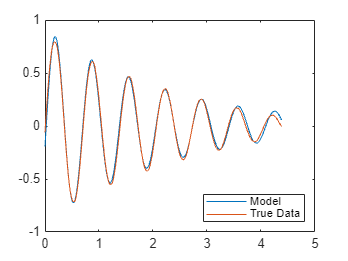


[simout,] = initial(sys_linear_est,[theta0, dtheta0], tVec);

plot(tVec, simout, tVec, y)
legend("Model", "True Data","Location","southeast")